# 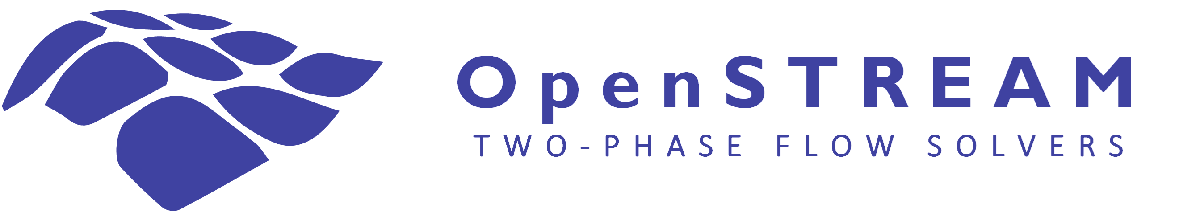

# Tutorial #2: Mixture solver capabilities

In this tutorial, you will explore the OpenSTREAM mixture solver through examples that demonstrate homogeneous and nonhomogeneous flow models, thermal nonequilibrium models, pressure-drop options, and transient simulation capabilities.

The selected geometry consists of a 3.5 m uniformly heated vertical tube with an inner diameter of 8.8 mm, followed by a 2 m adiabatic section with the same diameter. The flow enters slightly subcooled and is progressively vaporized through the heated section. Note that when the same case is simulated with the annular-flow solvers in Tutorials 4 and 5, the conditions lead to transition to annular two-phase flow, followed by film depletion near the end of the heated section and film regeneration through droplet deposition in the downstream adiabatic section.

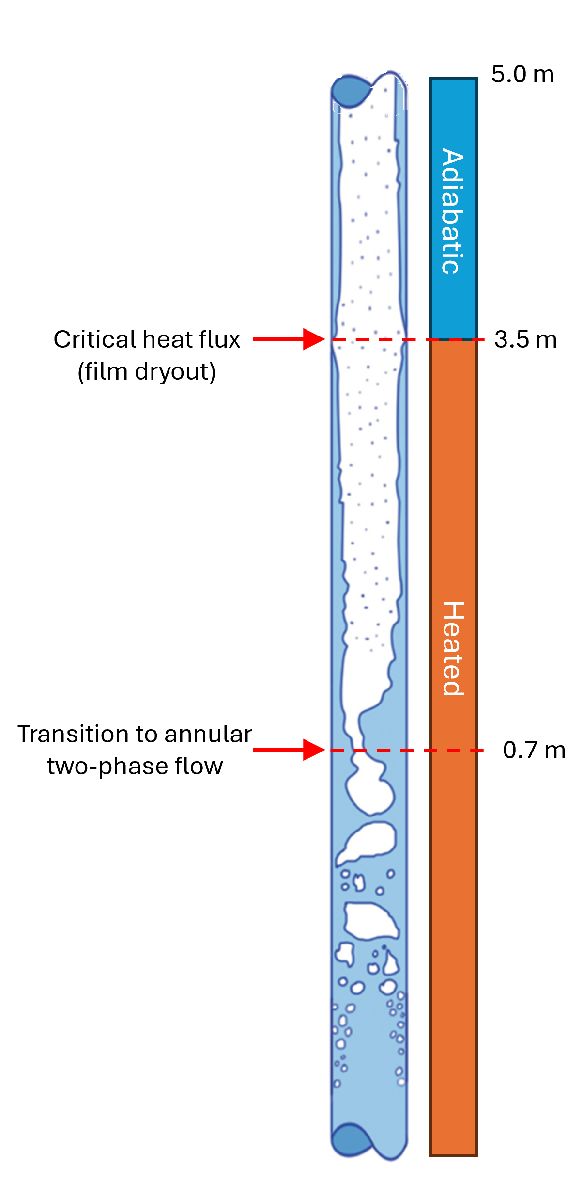

Learning objectives:

- Input files

- Homogeneous Equilibrium Model (HEM)

- Nonhomogeneous models

- Thermal nonequilibrium models

- Pressure-drop models

- Transient simulation

*Note: This tutorial is designed for use with output displayed inline (View > Output Inline) in the MATLAB Live Editor. Any animations are displayed in separate pop-up figure windows and can be played continuously or inspected one stored time step at a time. Animations and their controls are not preserved in static Markdown, HTML, or PDF exports.*

**Important**

*The physical models and closure relations selected in this tutorial are used for educational and demonstration purposes. Their use does not imply that they are appropriate, recommended, or validated for the simulated conditions. The calculated results should therefore be interpreted as illustrations of the solver framework and its capabilities, rather than as validated predictions. Before applying OpenSTREAM to a technical study, assess the assumptions, applicability range, and validation basis of every selected model.*

## Set up the MATLAB path

Clear existing variables from the workspace.

clearvars

When this tutorial is run directly from the tutorials folder, the OpenSTREAM root directory is one level above the current folder.

osp = './..';
addpath(osp);

## Input files

All input files required by this tutorial are provided in the openstream/inputs folder.

Import the input, solver, and mixture-solver packages.

import Inputs.*
import Solvers.*
import Solvers.Mixture.*

Display the physical-model input file and locate the TUTORIAL2 entries.

type('../inputs/models.inp')

All tutorial cases use 100 axial nodes and water as the working fluid.  Model selections that are not specified use their documented defaults.

The following model sets are used:

- TUTORIAL2A uses the default mixture-model selections and therefore  represents a Homogeneous Equilibrium Model (HEM).

- TUTORIAL2B selects the SLIP void-fraction model with a phase-velocity  ratio of 2.

- TUTORIAL2C selects the BESTION drift-flux void-fraction model.

- TUTORIAL2D combines the BESTION drift-flux model with the SAHAZUBER  empirical thermal-nonequilibrium model for subcooled boiling.

- TUTORIAL2E combines the BESTION drift-flux model with the Mixture Relaxation Model (MRM).

- TUTORIAL2F changes the wall-friction treatment.

- TUTORIAL2G adds local pressure-loss coefficients.

Display the numerical-option input file and locate the DEFAULT entry.

type('../inputs/options.inp')

No numerical options are specified for DEFAULT, so the simulations use the documented default settings.

Display the geometry input file and locate the TUTORIAL1 entry.

type('../inputs/geom.inp')

Geometry inputs use SI units. ANGLE is optional and defaults to 0, corresponding to a vertical upward test section. Specifying AREA and PERIM separately allows arbitrary cross-sectional shapes. Here, AREA and PERIM correspond to a circular tube with an inner diameter of 8.8 mm.

Display the steady-state boundary-condition file.

type('../inputs/tutorial1.inp')

A single time entry defines a steady-state case. WMESH specifies the axial segment lengths and WPOWER specifies the corresponding relative wall-power distribution. The case consists of a 3.5 m uniformly heated section followed by a 2 m adiabatic section. WMESH and WPOWER are optional. If omitted, uniform heating is assumed.

## Homogeneous Equilibrium Model (HEM)

The default mixture-solver selections assume hydrodynamic and thermal equilibrium, including equal phase velocities.

Each InputSet reads the physical-model, numerical-option, geometry, and boundary-condition files. Because each file can contain several input sets, the ID of the required set must be specified.

% Construct the inputSet.
warning off
inputSetA = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2A', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverA = MixtureSolver(inputSetA);
mixSolverA.solve();

At each pseudo-time step, the solver reports pointwise iteration results, including residuals for mixture mass flow rate, pressure, and enthalpy.

Steady-state convergence is accepted when the temporal convergence criteria and the required final pointwise convergence criteria are met.

Calling plotz without arguments generates plots for the principal output quantities. The display name-value argument selects specific quantities.

% Plot the axial wall-heat-flux distribution.
mixSolverA.plotz('display','HFLUX','resize',1);

The plot verifies that heating is uniform over the first 3.5 m and zero over the 2 m adiabatic section.

% Plot the axial mass-flow-rate distributions.
mixSolverA.plotz('display','W','resize',1);

Vapor appears when the equilibrium quality becomes nonnegative. Vapor mass then increases through the uniformly heated section and remains constant through the adiabatic section, as expected for the HEM.

% Plot the vapor volumetric ratio (void fraction) and vapor mass ratio.
mixSolverA.plotz('display','VR','resize',1);

Vapor mass quality and void fraction begin to increase when equilibrium quality becomes nonnegative.

% Save the solver object if desired. It can later be restored with load.
mixSolverA.save('name','mixSolverA','showpath',false);

## Nonhomogeneous models

The following cases allow different liquid and vapor velocities. The phase-velocity relationship is represented first by a fixed slip ratio and then by a drift-flux void-fraction model.

### Slip void-fraction model

TUTORIAL2B sets VOID = SLIP and SLIP = 2.

% Construct the inputSet.
warning off
inputSetB = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2B', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverB = MixtureSolver(inputSetB);
mixSolverB.solve();

% Plot vapor mass quality and void fraction.
mixSolverB.plotz('display','VR','resize',1);

Thermal equilibrium gives the same vapor mass quality as in the HEM case, while the imposed phase-velocity slip changes the void fraction.

% Plot the phase velocities.
mixSolverB.plotz('display','U','resize',1);

The vapor velocity is twice the liquid velocity, as prescribed by the selected slip ratio.

### Drift-flux void-fraction model

TUTORIAL2C sets VOID = BESTION. The BESTION model is one of the available drift-flux correlations implemented in OpenSTREAM.

% Construct the inputSet.
warning off
inputSetC = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2C', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverC = MixtureSolver(inputSetC);
mixSolverC.solve();

% Plot vapor mass quality and void fraction.
mixSolverC.plotz('display','VR','resize',1);

Thermal equilibrium again gives the same vapor mass quality, while the drift-flux relationship produces a varying difference between liquid and vapor velocities and therefore a different void-fraction distribution.

% Plot the phase velocities.
mixSolverC.plotz('display','U','resize',1);

The vapor velocity is higher than the liquid velocity, with a nonconstant slip ratio determined by the BESTION drift-flux model.

## Thermal nonequilibrium models

The following cases allow the vapor mass quality to differ from the equilibrium quality. An empirical subcooled-boiling model and the Mixture Relaxation Model are demonstrated.

### Empirical subcooled-boiling model

TUTORIAL2D combines VOID = BESTION with THERMALNONEQ = SAHAZUBER.

% Construct the inputSet.
warning off
inputSetD = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2D', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverD = MixtureSolver(inputSetD);
mixSolverD.solve();

% Plot vapor mass quality, equilibrium quality, and void fraction.
mixSolverD.plotz('display','VR','resize',1);

Vapor mass quality becomes positive near the inlet while equilibrium quality remains negative. The associated increase in void fraction is characteristic of subcooled boiling represented by the Saha-Zuber model.

### Mixture Relaxation Model (MRM)

TUTORIAL2E sets THERMALNONEQ = MRM. The MRM introduces vapor mass and energy conservation equations to represent nonequilibrium interfacial evaporation and condensation. This case uses the default relaxation-time selections.

% Construct the inputSet.
warning off
inputSetE = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2E', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverE = MixtureSolver(inputSetE);
mixSolverE.solve();

% Plot vapor mass quality, equilibrium quality, and void fraction.
mixSolverE.plotz('display','VR','resize',1);

Vapor mass quality becomes positive while equilibrium quality remains negative near the inlet. The MRM therefore also represents subcooled boiling for this case. A dedicated tutorial can examine the MRM and its use for post-boiling-transition nonequilibrium in greater detail.

## Pressure-drop models

OpenSTREAM stores the cumulative pressure-drop components separately. These include gravitational, wall-friction, spatial-acceleration, temporal-acceleration, and local-loss contributions.

### Axial pressure-drop components

Use the previously solved Saha-Zuber case.

mixSolverD.plotz('display','DP','resize',1);

The pressure reference is the inlet. The plotted cumulative pressure drop is shown as a positive loss even though pressure decreases axially. For this steady-state unobstructed case, the local and temporal-acceleration contributions are zero. The spatial-acceleration contribution remains constant through the adiabatic section. Wall friction is the dominant contribution for this modeled case, followed by spatial acceleration.

### Wall friction

TUTORIAL2F selects a Blasius-type single-phase wall-friction relation and the EPRI two-phase friction multiplier.

% Construct the inputSet.
warning off
inputSetF = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2F', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverF = MixtureSolver(inputSetF);
mixSolverF.solve();

% Plot the cumulative pressure-drop components.
mixSolverF.plotz('display','DP','resize',1);

Relative to the default case, the selected wall-friction treatment increases the wall-friction contribution and therefore the total pressure drop for this modeled case.

### Local pressure losses

TUTORIAL2G adds five local perturbations at elevations of 1, 2, 3, 4, and 5 m, each with a loss coefficient of 0.5, and selects the homogeneous two-phase local-loss multiplier.

% Construct the inputSet.
warning off
inputSetG = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2G', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial1.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverG = MixtureSolver(inputSetG);
mixSolverG.solve();

% Plot the cumulative pressure-drop components.
mixSolverG.plotz('display','DP','resize',1);

The local perturbations produce discrete increases in cumulative local pressure loss and therefore in the total pressure drop.

## Transient simulation

This case demonstrates a power decrease to half of the nominal value over 1 s. The transient boundary conditions are stored in tutorial2_transient.inp.

type('../inputs/tutorial2_transient.inp')

Multiple time entries define the transient. System pressure, inlet enthalpy, inlet mass flow rate, total power, and axial power distribution can vary with time. Only power varies in this example. TUTORIAL2D retains the BESTION drift-flux and Saha-Zuber subcooled-boiling selections.

% Construct the inputSet.
warning off
inputSetH = InputSet( ...
    modelFilePath          = [osp '/inputs/models.inp'], ...
    modelID                = 'TUTORIAL2D', ...
    optionsFilePath        = [osp '/inputs/options.inp'], ...
    optionsID              = 'DEFAULT', ...
    geometryFilePath       = [osp '/inputs/geom.inp'], ...
    geometryID             = 'TUTORIAL1', ...
    bcFilePath             = [osp '/inputs/tutorial2_transient.inp'], ...
    sessionParentDir       = fullfile(pwd,'outputs'), ...
    overwriteSessionFiles = true, ...
    LOGMODE                = 'BOTH');
warning on

% Create and solve the mixture solver.
mixSolverH = MixtureSolver(inputSetH);
mixSolverH.solve();

The solver first obtains the initial steady-state solution through pseudo-time advancement and then calculates the prescribed transient.

% Plot heat flux and vapor ratios for all stored times.
mixSolverH.plotz( ...
    'display', {'HFLUX','VR'}, ...
    'arrangement', 'horizontal', ...
    'resize', 1);

 The initial state matches the steady-state TUTORIAL2D solution. The plotz controls can be used to step through or play the stored transient states.

## Summary

In this tutorial, you used the mixture solver with homogeneous, fixed-slip, drift-flux, empirical thermal-nonequilibrium, and relaxation-based models. You also examined pressure-drop components, changed wall-friction and local loss treatments, and simulated a power transient.